Subject sub-959, Rec_03 processed successfully.


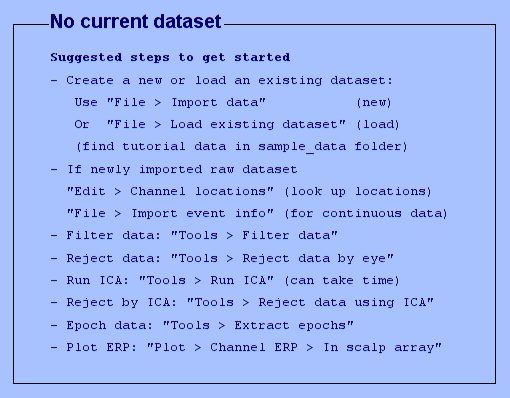

%% Clear workspace and initialize
close all; clear; clc;

% Define base directories
baseInputDir  = 'O:\Tech_NeuroData\DDRC';
baseOutputDir = 'O:\Tech_NeuroData\Code\Usleep_set_files';

% Define subject mapping for subjects with additional recordings.
% Format: {inputFolderName, subjectID, totalRecordings}
% Only subjects that are not deleted and with additional recordings (i.e. total recordings > 1) are included.
subjectMap = {
    %'2_AD_03', 'sub-298', 3;
    %'2_AD_06', 'sub-856', 2;
    %'2_AD_07', 'sub-360', 3;
    %'2_AD_09', 'sub-749', 3;
    %'2_AD_10', 'sub-462', 3;
    %'2_AD_12', 'sub-263', 3;
    %'2_AD_13', 'sub-689', 2;
    %'2_AD_15', 'sub-913', 2;
    %'2_AD_17', 'sub-538', 3;
    %'2_AD_18', 'sub-443', 2;
    %'2_AD_21', 'sub-98', 3;
    %'2_AD_22', 'sub-958', 3;
    %'2_AD_23', 'sub-971', 3;
    %'3_DLB_01', 'sub-849', 3;
    %'3_DLB_04', 'sub-3127', 3;
    '3_DLB_05', 'sub-398', 3;  
    '3_DLB_06', 'sub-3958', 2; % Note: Although Rec_01, Rec_02 and Rec_03 exist, only Rec_02 yielded a file.
    '3_DLB_07', 'sub-3971', 2;
    '3_DLB_08', 'sub-485', 3;
    '3_DLB_09', 'sub-3422', 3;
    '3_DLB_10', 'sub-959', 3;
};

skippedRecordings = {};

% Loop through each subject in the mapping
for i = 1:size(subjectMap, 1)
    inputFolderName = subjectMap{i,1};
    subjectID       = subjectMap{i,2};
    totalRecordings = subjectMap{i,3};
    
    fprintf('\nProcessing subject %s (%s) with %d recordings...\n', subjectID, inputFolderName, totalRecordings);
    
    % Build the full input path for the subject
    subjectInputPath = fullfile(baseInputDir, inputFolderName);
    
    % Process additional recordings (starting from recording 2)
    for recNum = 2:totalRecordings
        try
            recFolder = fullfile(subjectInputPath, sprintf('Rec_%02d', recNum));
            if ~exist(recFolder, 'dir')
                error('Recording folder %s not found for %s', sprintf('Rec_%02d', recNum), subjectID);
            end
            
            % List subdirectories in recFolder (representing the coreg folder)
            subDirs = dir(recFolder);
            subDirs = subDirs([subDirs.isdir]);
            subDirs = subDirs(~ismember({subDirs.name}, {'.','..'}));
            if isempty(subDirs)
                error('No coreg subfolder found in %s for %s', recFolder, subjectID);
            end
            
            % Use the first (or only) subfolder in recFolder
            coregFolder = fullfile(recFolder, subDirs(1).name);
            
            % Search for .Poly5 files (handling both .Poly5 and .poly5 extensions)
            poly5Files = dir(fullfile(coregFolder, '*.Poly5'));
            if isempty(poly5Files)
                poly5Files = dir(fullfile(coregFolder, '*.poly5'));
            end
            
            if isempty(poly5Files)
                error('.Poly5 file not found in %s for %s', coregFolder, subjectID);
            end
            
            % Prefer a file that starts with '2ID_'
            poly5Names = {poly5Files.name};
            matchIdx = find(strncmpi(poly5Names, '2ID_', 4));
            if isempty(matchIdx)
                % Fallback: use the first available file
                matchIdx = 1;
            else
                matchIdx = matchIdx(1);
            end
            
            currentFile = poly5Files(matchIdx).name;
            fprintf('Processing file %s in %s...\n', currentFile, coregFolder);
            
            %% Conversion pipeline
            
            % Define channel labels (2x6 ear-EEG channels plus additional labels)
            ChannelLabels = {'ELA', 'ELB', 'ELC', 'ELT', 'ELE', 'ELI', ...
                'ERA', 'ERB', 'ERC', 'ERT', 'ERE', 'ERI', ...
                '13', '14', '15', '16', '17', '18', '19', '20', '21', '22', '23', '24', '25', '26', '27', '28', '29', '30', '31', '32'};
            
            % Load the Poly5 file using pop_loadpoly5_1
            RecordsFolder = coregFolder;
            EEG = pop_loadpoly5_1('filepath', RecordsFolder, 'filename', currentFile, ...
                'ref_ch', [], 'NaNdiscSamples', true, 'ChannelsDiscThd', 1, 'EnableSaturationDisc', true, ...
                'EnableSameValueDisc', false, 'ChannelLabels', ChannelLabels);
            
            %% Keep only the 2x6 ear-EEG channels
            if EEG.nbchan < 12
                EEG = pop_select(EEG, 'channel', 1:EEG.nbchan);
            else
                EEG = pop_select(EEG, 'channel', 1:12);
            end
            
            %% Bandpass filtering (0.5 - 40 Hz)
            fprintf('Performing bandpass filtering...\n');
            for iCh = 1:EEG.nbchan
                EEG.data(iCh, :) = EEG.data(iCh, :) - nanmean(EEG.data(iCh, :));
            end
            EEG = pop_eegfiltnew(EEG, 0.5, 40);
            
            %% Replace NaNs with zeros (EDF does not support NaNs)
            EEG.data(isnan(EEG.data)) = 0;
            
            %% Save as EDF file
            % The output directory is assumed to be already created
            outputDir = fullfile(baseOutputDir, subjectID, sprintf('ses-%02d', recNum));
            if ~exist(outputDir, 'dir')
                error('Output directory %s does not exist for %s', outputDir, subjectID);
            end
            
            % Define the output filename (BIDS compliant)
            new_filename = sprintf('%s_ses-%02d_task-sleep_eeg.edf', subjectID, recNum);
            Savefilename = fullfile(outputDir, new_filename);
            fprintf('Saving EDF file as %s...\n', Savefilename);
            
            % Write the EDF file using pop_writeeeg
            pop_writeeeg(EEG, Savefilename, 'TYPE', 'EDF');
            fprintf('Subject %s, Rec_%02d processed successfully.\n', subjectID, recNum);
            
        catch ME
            fprintf('Error processing subject %s, Rec_%02d: %s\n', subjectID, recNum, ME.message);
            skippedRecordings{end+1} = sprintf('%s Rec_%02d', subjectID, recNum);
        end
    end
end


%% Report skipped recordings, if any
if ~isempty(skippedRecordings)
    fprintf('\nThe following recordings were skipped due to errors:\n');
    disp(skippedRecordings);
else
    fprintf('\nAll recordings processed successfully.\n');
end


All recordings processed successfully.
